# Creating graphs from survey data

## Loeschenmuehle

First we create from a distance matrix created with Google Earth a good enough graph embedding of the survey surroundings to embed onto the satellite map.

addpath maps functions

D = readDistanceMatrix("maps/muehle/distances.txt");
[X,E] = mdscale(D,2);
X = X - X(1,:);

The calculated embedding is mirrored respective to the real map, therefore we mirror the given embedding.

X(:,1) = -X(:,1);

In addition, we need to rotate the embedding to fit to the real map.

The measured angle between Loeschenmuehle and Unterkaierberg is 177.8 in a clockwise fashion from north. As we start in Matlab with angle 0 to the right we rotate by 90° "less".

(see thesis\survey\map_angle.png)

measuredAngle = -177.8 + 90;
angle13 = atan2(X(3,2)-X(1,2),X(3,1)-X(1,1));

With this we can rotate the whole embedding to fit the real map graph.

fitAngle = measuredAngle - rad2deg(angle13);
emb = (rotationMatrix(fitAngle)*X')';

To check, let us plot the embedding of the surroundings of Loeschenmuehle.

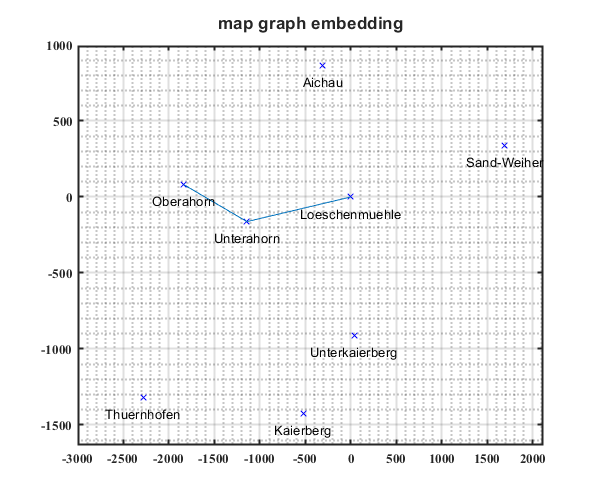

figure
labels = {'Loeschenmuehle','Sand-Weiher','Unterkaierberg','Kaierberg','Thuernhofen','Oberahorn','Unterahorn','Aichau'};

t = tiledlayout(1,1);
t.Title.String = "map graph embedding";
t.Title.FontWeight = 'bold';        
nexttile

plot(emb(:,1),emb(:,2),"xb")
line([emb(1,1),emb(7,1),emb(6,1)],[emb(1,2),emb(7,2),emb(6,2)])
labelpoints(emb(:,1),emb(:,2),labels,'S',0.2,1);
grid minor

exportgraphics(t,"plots\survey\graph_mds.png","Resolution",300);

figure

For comparing our graph with the satellite map, let's import the latter.

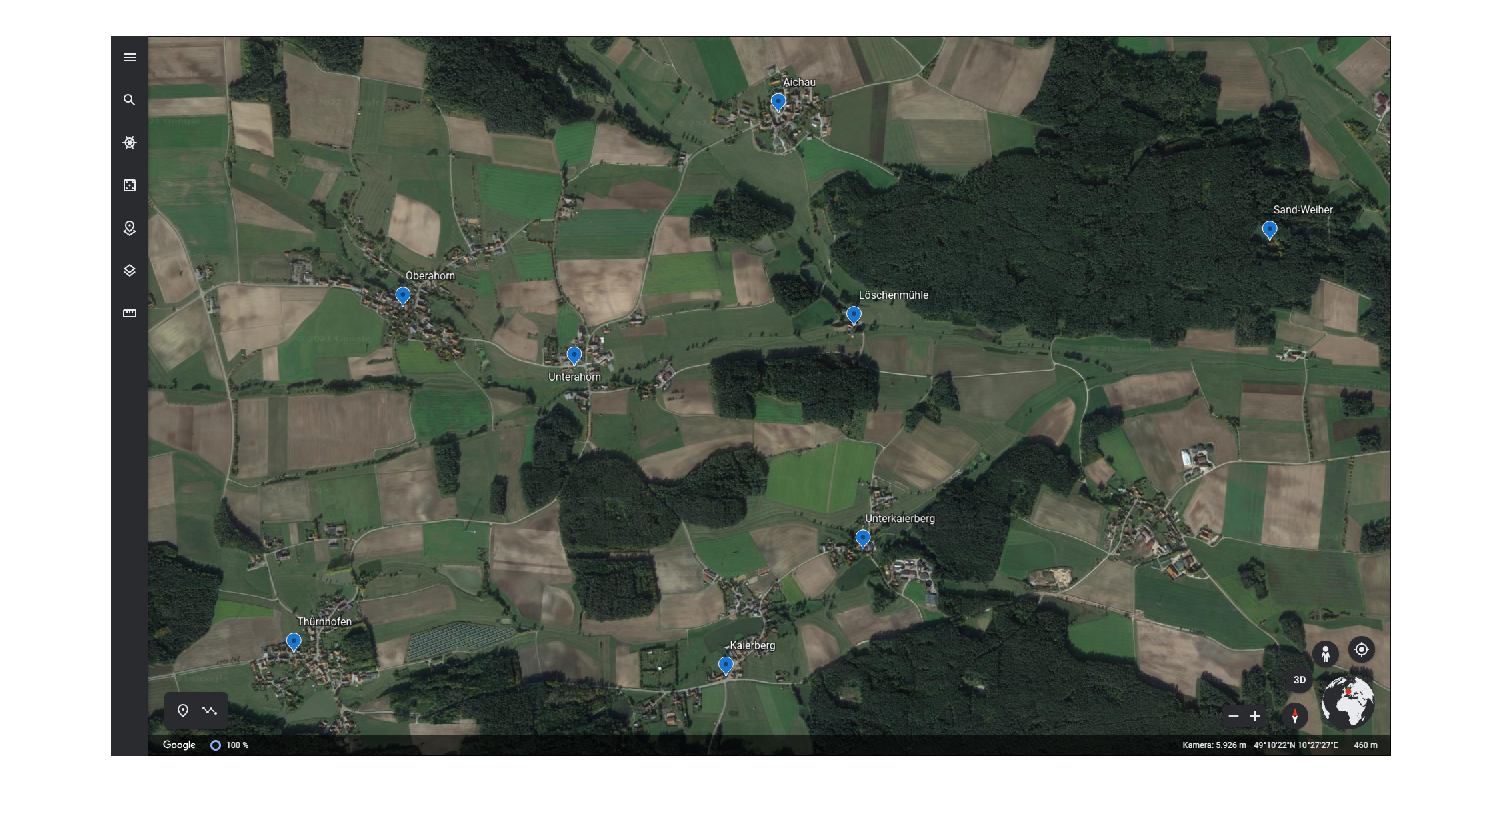

path = "maps/muehle/";
map = imread(path + "graph_earth.png");
imshow(map);

As our embedding of the graph is fit to the satellite map, we can save this embedding as initial muehle graph in the respective **nodes.txt**.

data = [(1:8)' emb zeros(8,1) zeros(8,1)];
data = [["label" "xPos" "yPos" "vote" "north"];zeros(1,5);data];
writematrix(data, "data\survey_correct\nodes.txt", ...
    'Delimiter','tab');

In addition we compute the angles from the correct embedding to save the edges in a file of the same format as the **"survey_" **edge files. The angles are computed by the **atan2()** function from the embedding.

angles = zeros(1,21);
count = 0;
for i = [1 6 7]
    for j = 1:8
        if i ~= j
            count = count + 1;
            angle = 90 - rad2deg(atan2(emb(j,2)-emb(i,2),emb(j,1)-emb(i,1)));
            angles(count) = angle;
        end
    end
end

data = [[ones(1,7) repmat(6,1,7) repmat(7,1,7)]; [2:8 1:5 7:8 1:6 8]; 0:20; ones(1,21); angles]';
data = [["from" "to" "label" "distance" "angle"];data];
writematrix(data, "data\survey_correct\edges.txt", ...
    'Delimiter','tab');

Interestingely enough, the hereby calculated angles are erroneous, that the calculated embedding varies significantely from the map version...

Is this only due to mathematical inaccuracy in the matlab environment?

Unfortunately, because of this, we cannot use this embedding as the overlay for the correct embedding version (map version).

% plotSurvey("survey_correct","Modus","ls","Which","both","Ov",true);
% plotSurvey("survey_correct","Modus","gd","Which","both","Ov",true);

% plotSurvey("survey_correct","Modus","ls","Which","bothPerception");
% plotSurvey("survey_correct","Modus","gd","Which","bothPerception");
% 
% plotSurvey("survey_correct","Modus","ls","Which","given");
% plotSurvey("survey_correct","Modus","gd","Which","given");
% 
% plotSurvey("survey_correct","Modus","ls","Which","givenPerception");
% plotSurvey("survey_correct","Modus","gd","Which","givenPerception");
% 
% plotSurvey("survey_correct","Modus","ls","Which","embedding");
% plotSurvey("survey_correct","Modus","gd","Which","embedding");
% 
% plotSurvey("survey_correct","Modus","ls","Which","embeddingPerception");
% plotSurvey("survey_correct","Modus","gd","Which","embeddingPerception");
% 
% plotSurvey("survey_correct","Modus","ls","Which","four");
% plotSurvey("survey_correct","Modus","gd","Which","four");
% 
% plotSurvey("survey_correct","Modus","ls","Which","overlay");
% plotSurvey("survey_correct","Modus","gd","Which","overlay");

Then we can create adequate visualizations of the survey data. With the function **plotSurvey()** the generated plots are saved in location **plots\survey\...**.

First are a comparison of the given embedding and their **ov **per participant with the calculated embedding minimizing the **ov**.

% plotSurveyAll("both");
% plotSurvey("survey_theo","both");
% plotSurvey("survey_jakob","both");
% plotSurvey("survey_ronja","both");
% plotSurvey("survey_helmut","both");
% plotSurvey("survey_leia","both");
% plotSurvey("survey_birgit","both");

We then can overlay the both graphs, where the given embedding is greyed out behind the calculated embedding. The scaling of this greyed out given embedding is done in the sense that the **distances** for both embeddings between Loeschenmuehle and Unterahorn **are equal**. No rotation is done though.

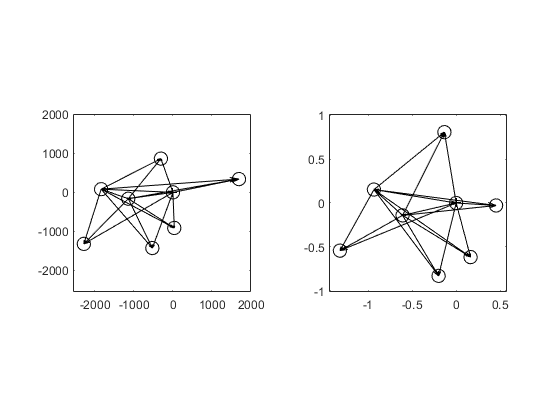

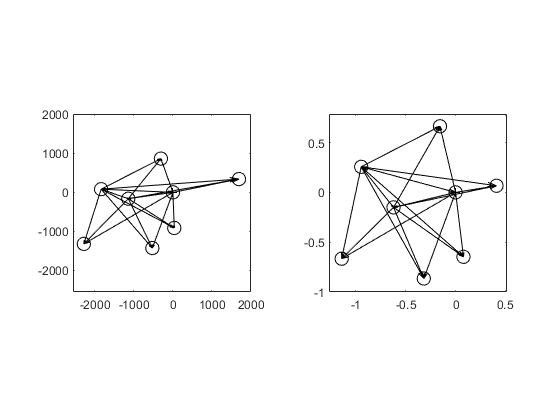

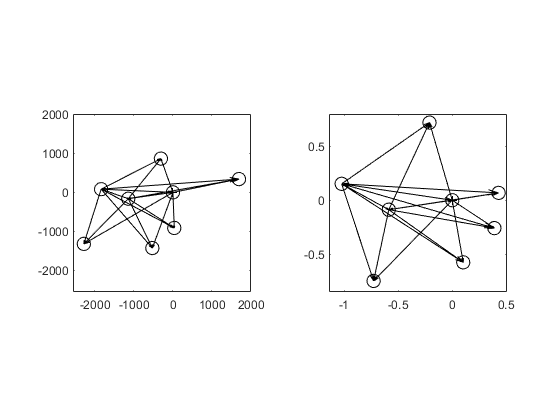

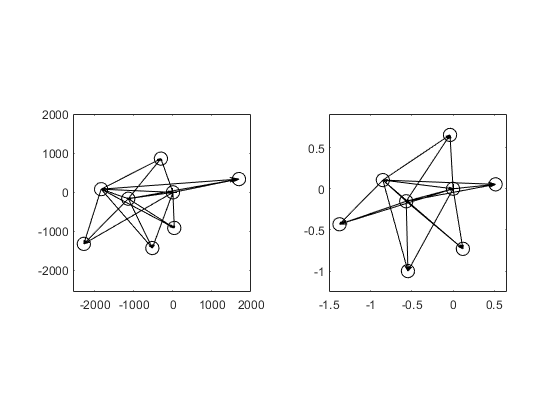

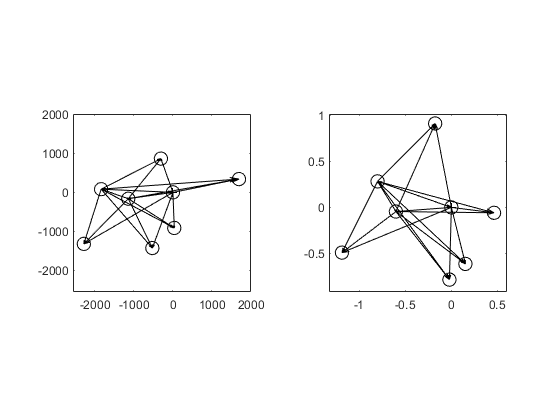

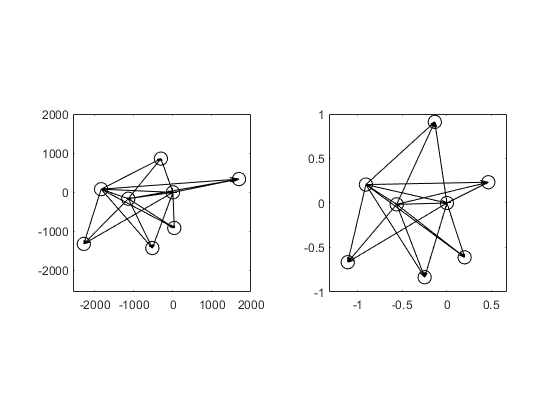

plotSurveyAll("overlay");

% plotSurvey("survey_theo","overlay");
% plotSurvey("survey_jakob","overlay");
% plotSurvey("survey_ronja","overlay");
% plotSurvey("survey_helmut","overlay");
% plotSurvey("survey_leia","overlay");
% plotSurvey("survey_birgit","overlay");

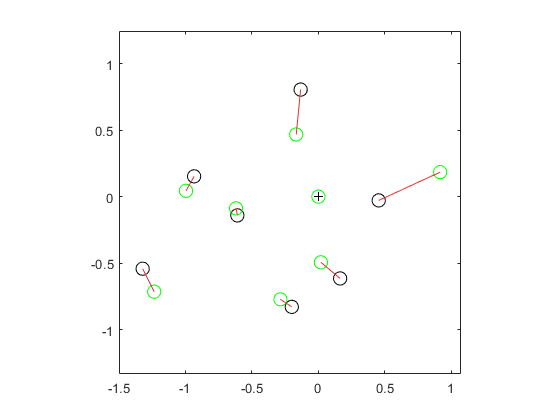

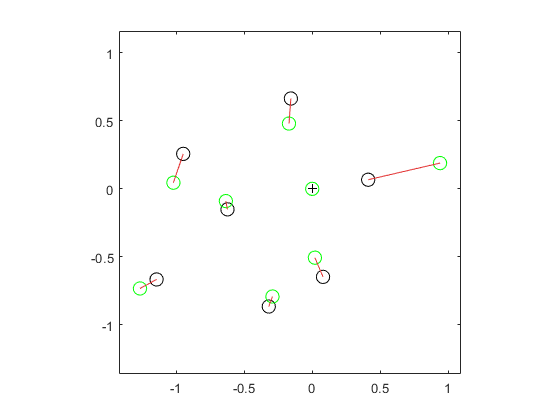

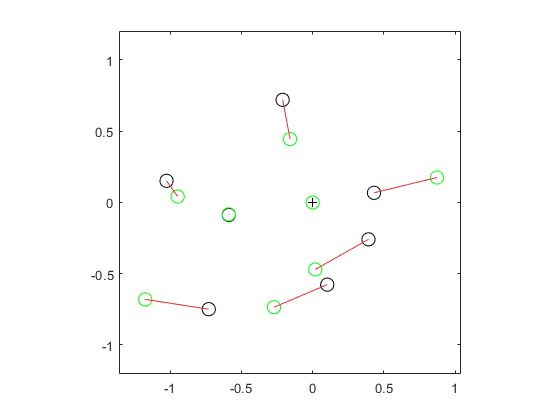

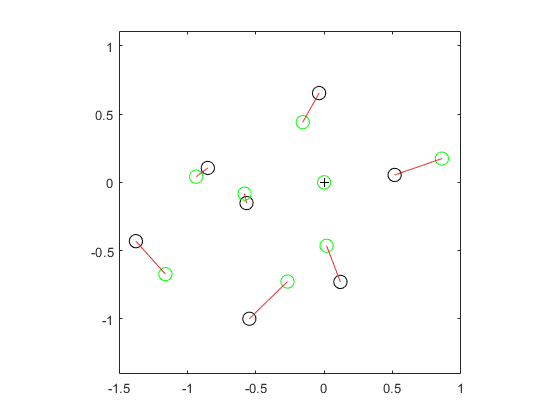

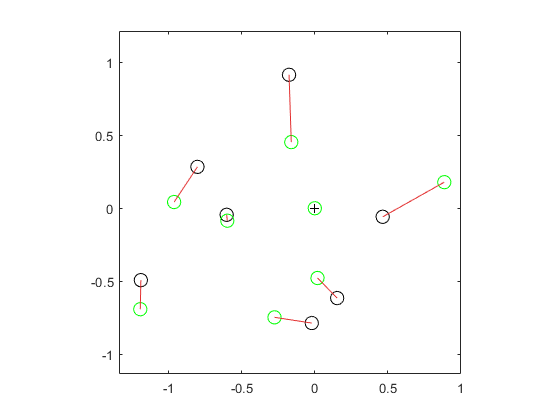

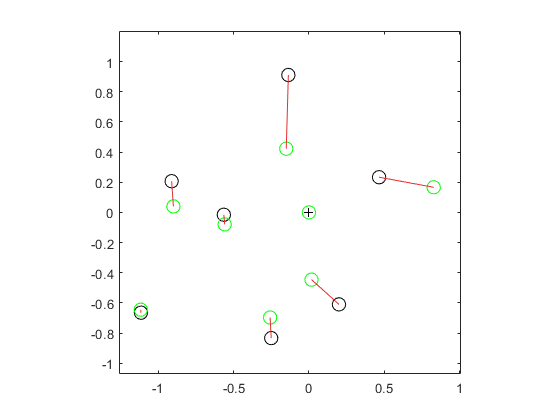

% plotSurveyAll("bothPerception");
% plotSurvey("survey_theo","bothPerception");
% plotSurvey("survey_jakob","bothPerception");

% plotSurvey("survey_ronja","bothPerception");
% plotSurvey("survey_helmut","bothPerception");
% plotSurvey("survey_leia","bothPerception");
% plotSurvey("survey_birgit","bothPerception");

In addition we can plot the embedding with the angular perception.

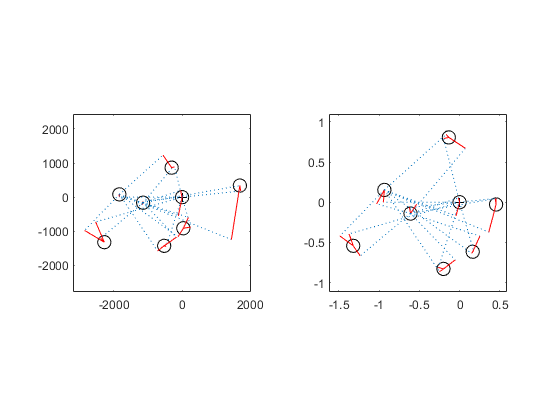

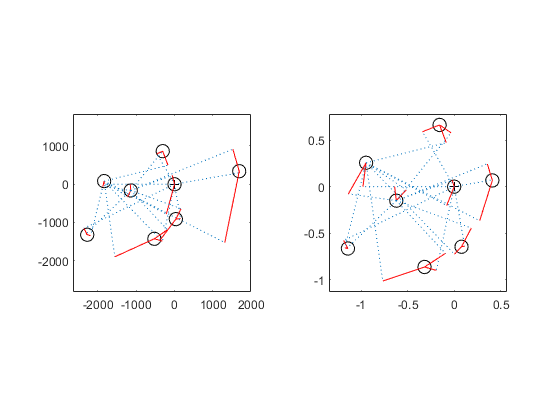

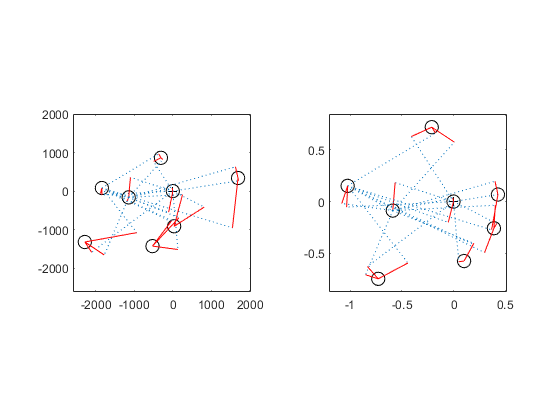

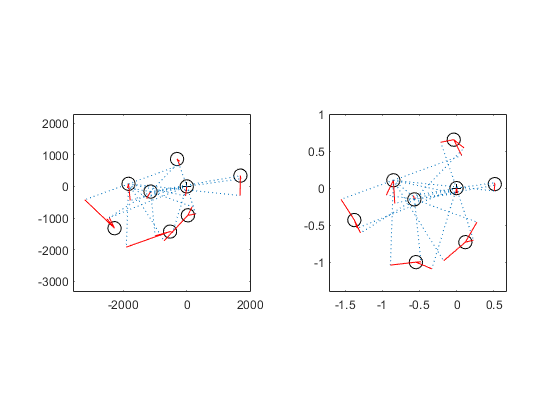

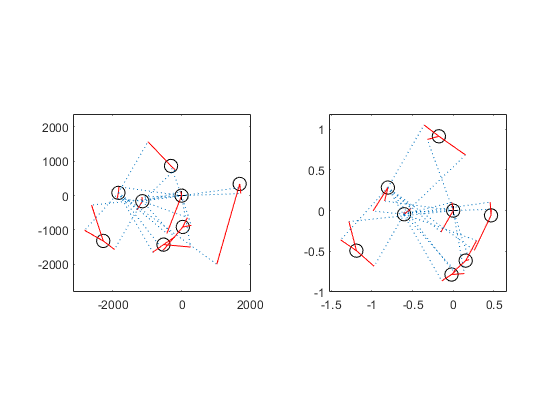

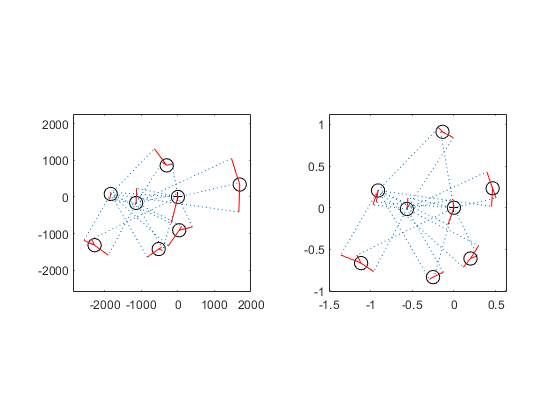

% plotSurveyAll("four");
% plotSurvey("survey_theo","four");
% plotSurvey("survey_jakob","four");
% plotSurvey("survey_ronja","four");

% plotSurvey("survey_helmut","four");
% plotSurvey("survey_leia","four");
% plotSurvey("survey_birgit","four");

To be flexible with the insertion of graph pictures in the thesis, we plot each participants given and calculated embedding with **ovs** respectively as well.

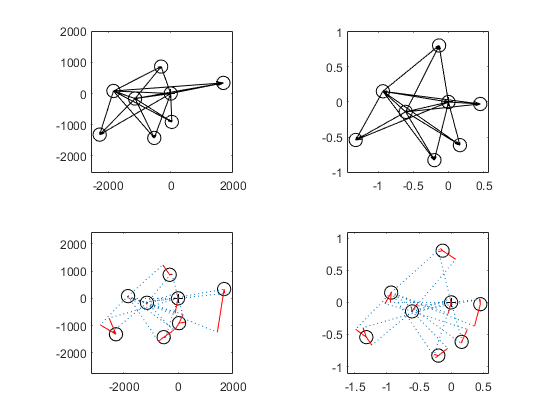

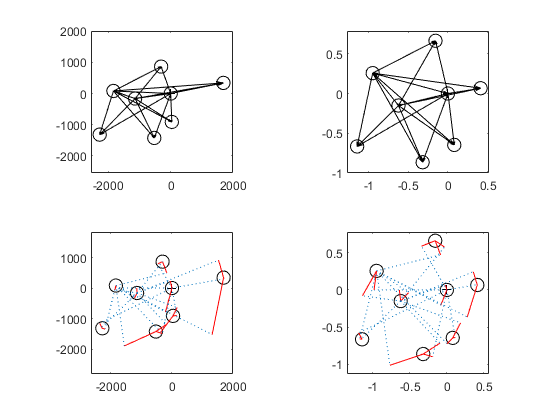

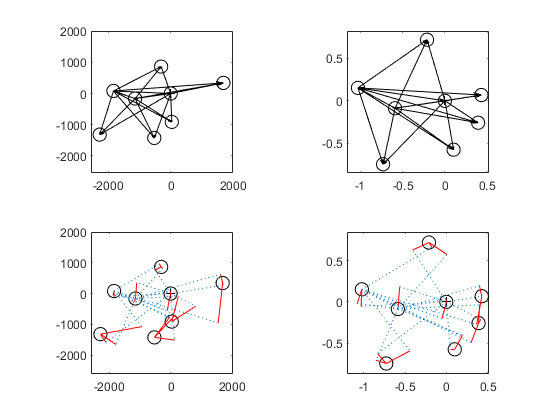

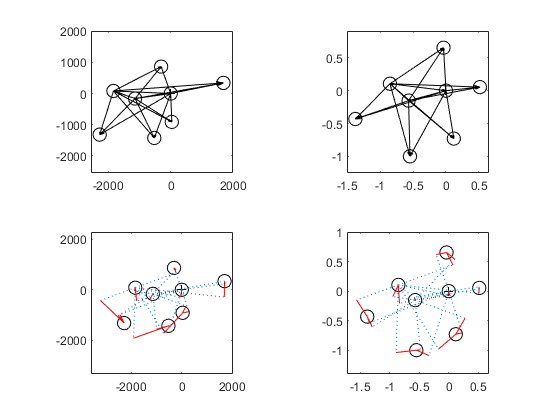

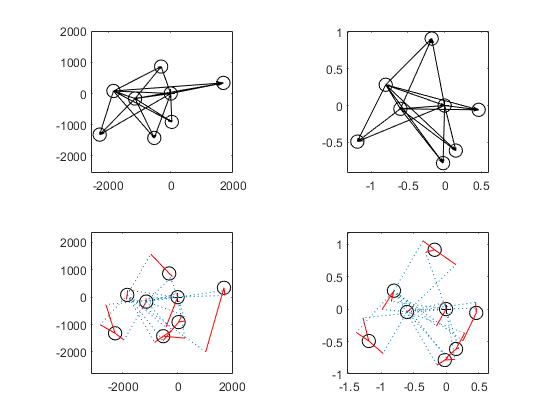

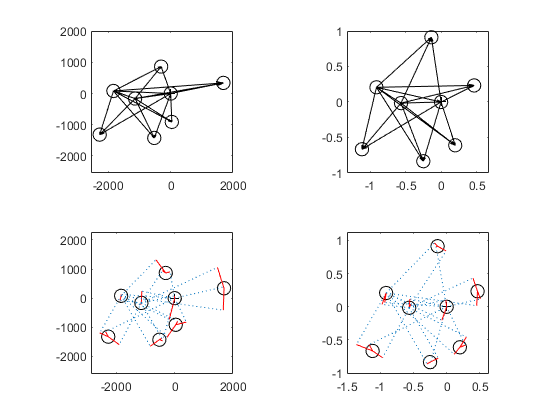

plotSurveyAll("given");

% plotSurvey("survey_theo","given");
% plotSurvey("survey_jakob","given");
% plotSurvey("survey_ronja","given");
% plotSurvey("survey_helmut","given");
% plotSurvey("survey_leia","given");
% plotSurvey("survey_birgit","given");

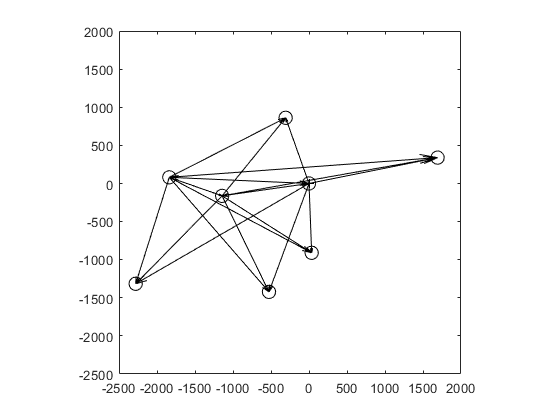

plotSurveyAll("embedding");

% plotSurvey("survey_theo","embedding");
% plotSurvey("survey_jakob","embedding");
% plotSurvey("survey_ronja","embedding");
% plotSurvey("survey_helmut","embedding");
% plotSurvey("survey_leia","embedding");
% plotSurvey("survey_birgit","embedding");

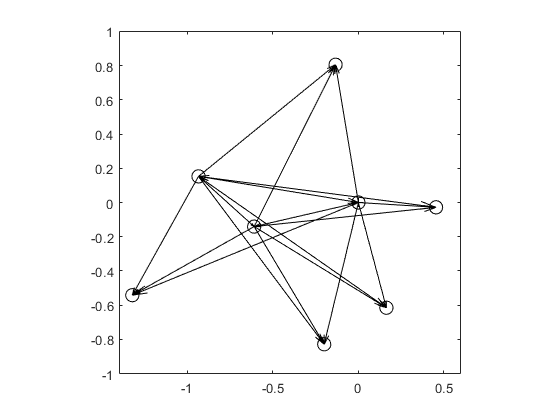

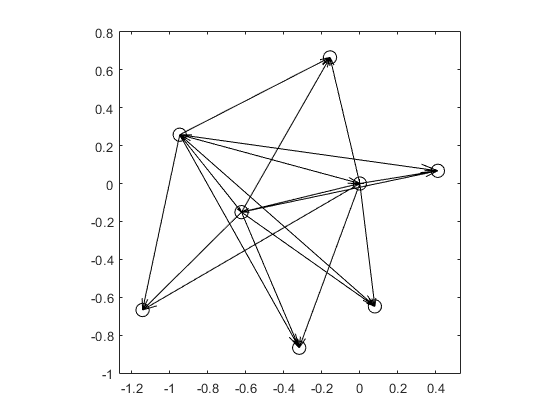

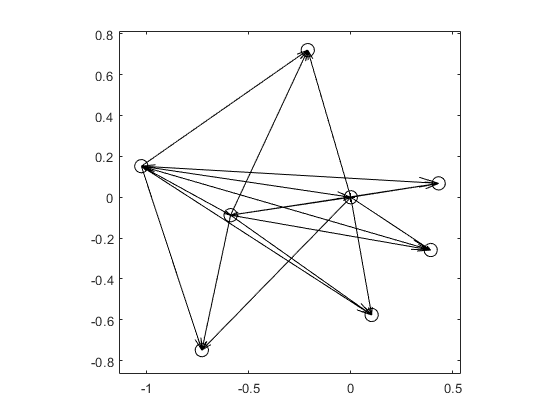

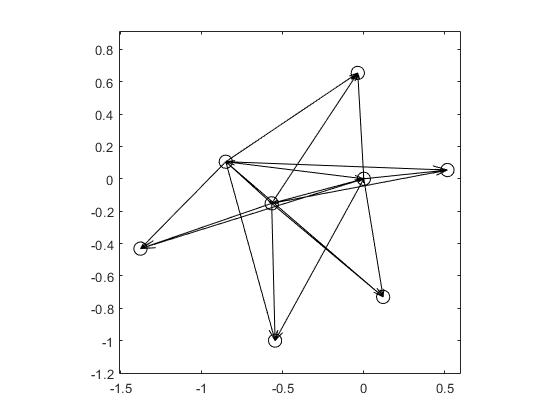

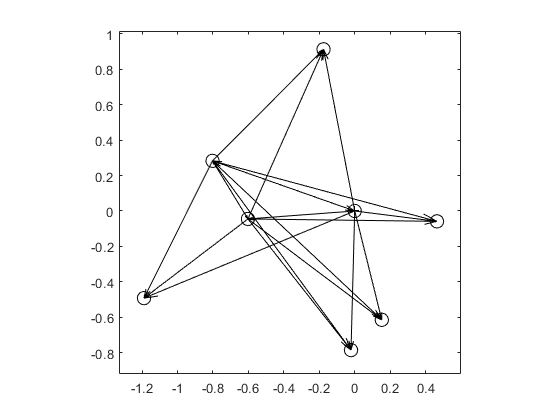

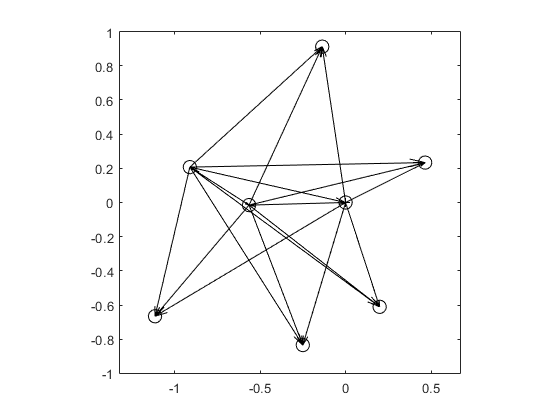

plotSurveyAll("givenPerception");

% plotSurvey("survey_theo","givenPerception");
% plotSurvey("survey_jakob","givenPerception");
% plotSurvey("survey_ronja","givenPerception");
% plotSurvey("survey_helmut","givenPerception");
% plotSurvey("survey_leia","givenPerception");
% plotSurvey("survey_birgit","givenPerception");

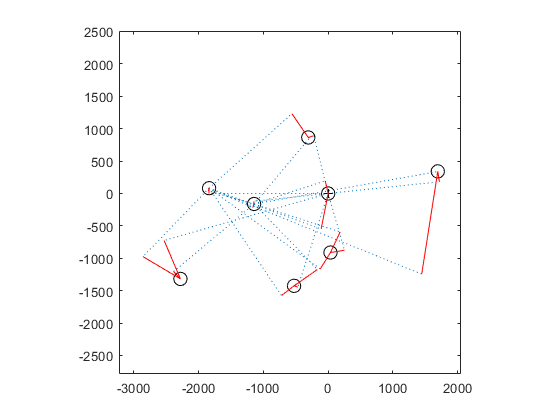

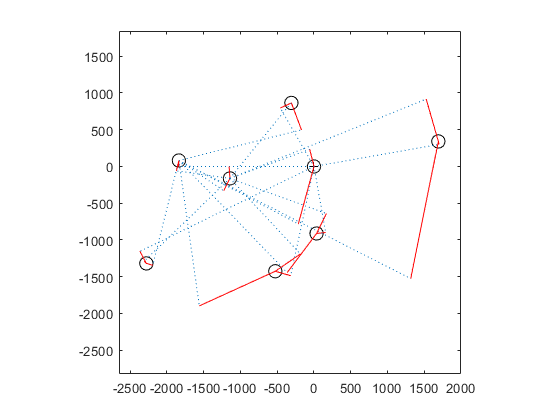

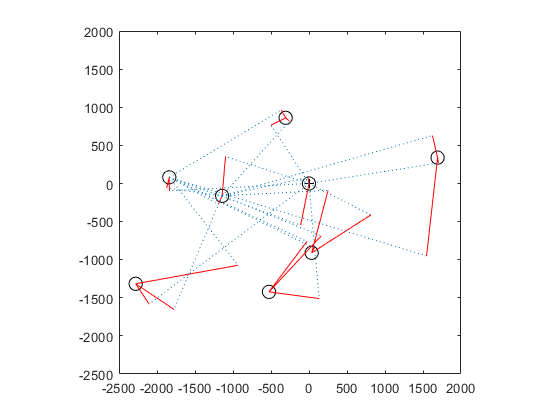

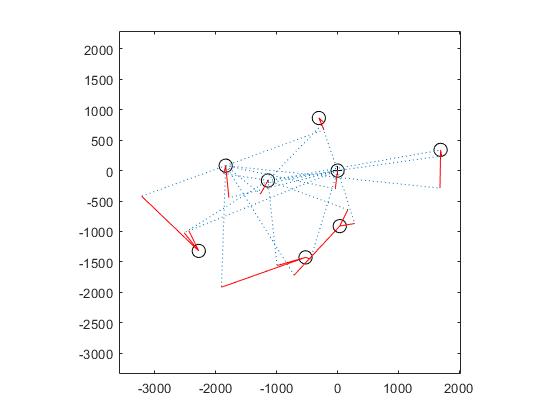

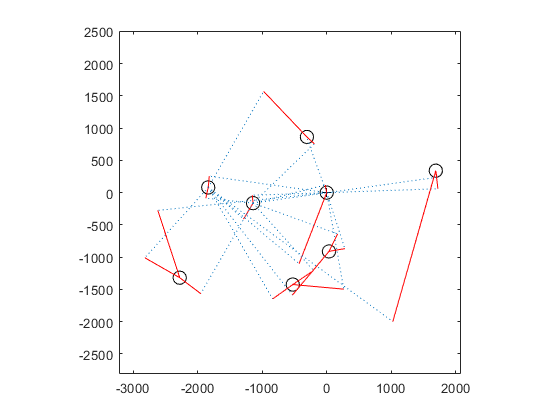

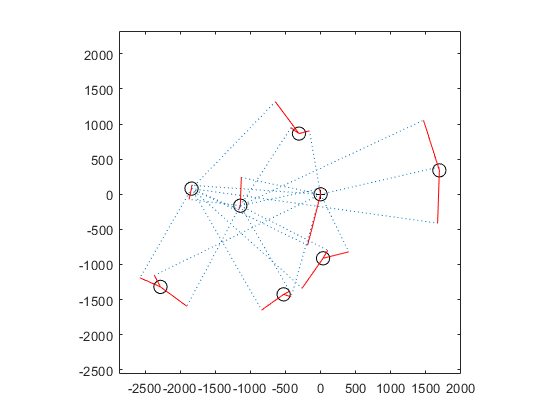

plotSurveyAll("embeddingPerception");

% plotSurvey("survey_theo","embeddingPerception");
% plotSurvey("survey_jakob","embeddingPerception");
% plotSurvey("survey_ronja","embeddingPerception");
% plotSurvey("survey_helmut","embeddingPerception");
% plotSurvey("survey_leia","embeddingPerception");
% plotSurvey("survey_birgit","embeddingPerception");

We can visualize in different ways. Best to test the most appealing graph representation.

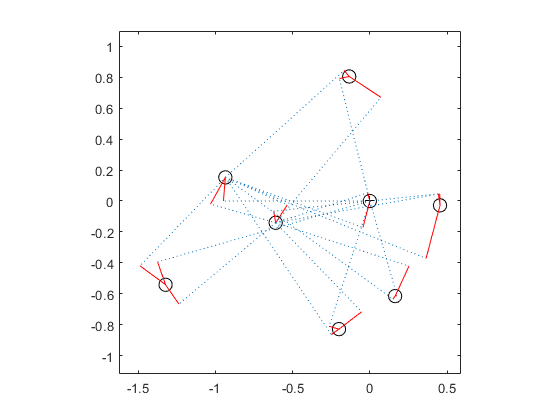

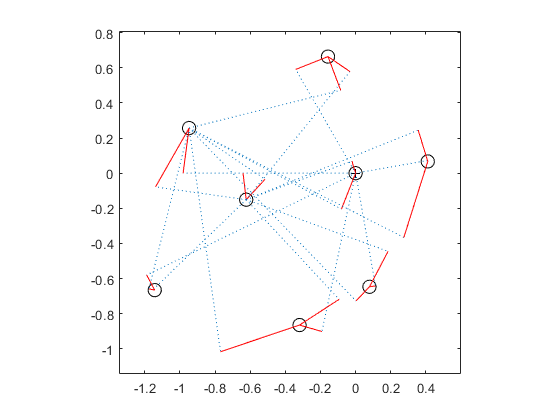

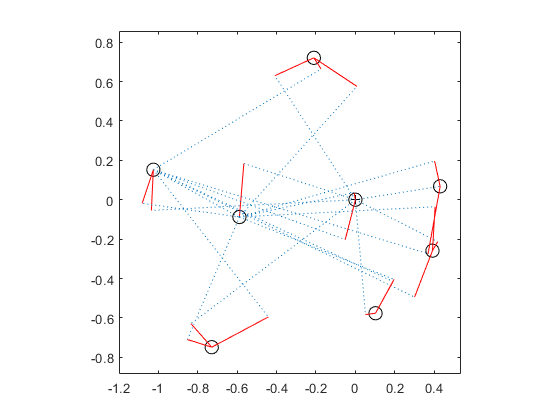

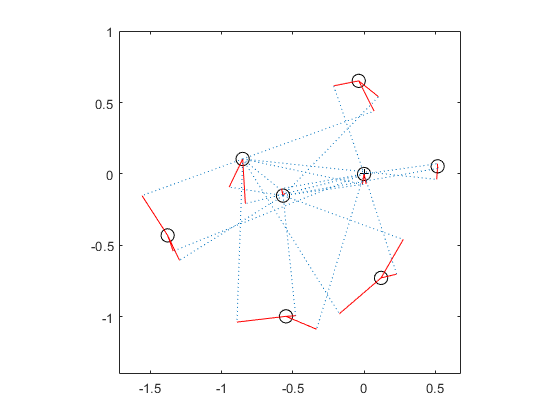

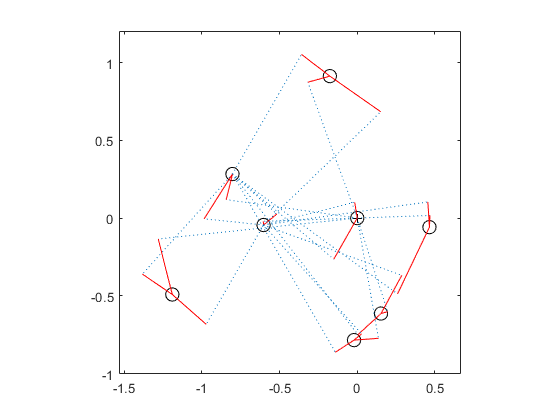

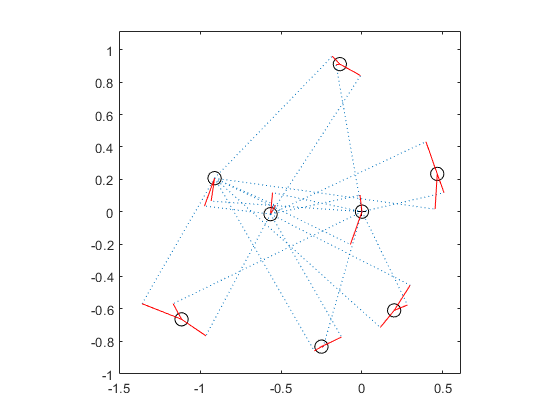

plotData("survey_theo",1,1,0,1,1,1,0,1,0,1,0);

plotData("survey_theo",1,1,0,1,1,1,0,1,1,1,0);

% plotCompare("survey_theo",1,[1,1]);
% plotCompareOptions("survey_theo",1,1,1,0,0,1,1,1,0,[1,1]);

## Functions


merging...
Elapsed time is 0.007661 seconds.

building M...
Elapsed time is 0.000188 seconds.

building P...
Elapsed time is 0.000081 seconds.


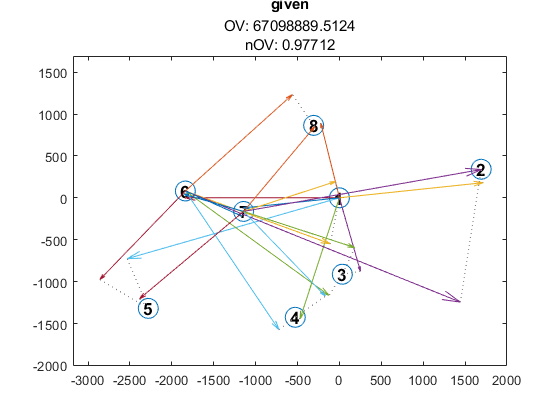

function R = rotationMatrix(theta)


merging...
Elapsed time is 0.007331 seconds.

building M...
Elapsed time is 0.000098 seconds.

building P...
Elapsed time is 0.000059 seconds.


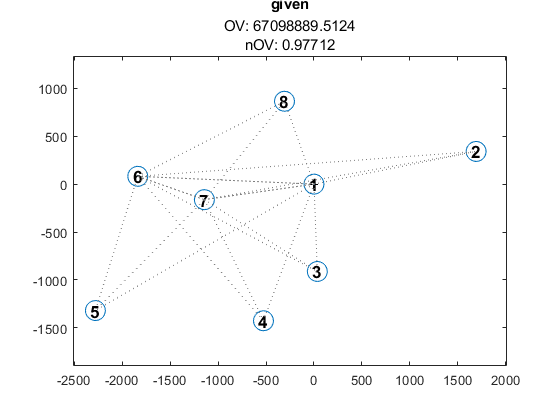

% creates the 2d rotation matrix for a given angle theta in degree


merging...
Elapsed time is 0.004597 seconds.

building M...
Elapsed time is 0.000107 seconds.

building P...
Elapsed time is 0.000058 seconds.


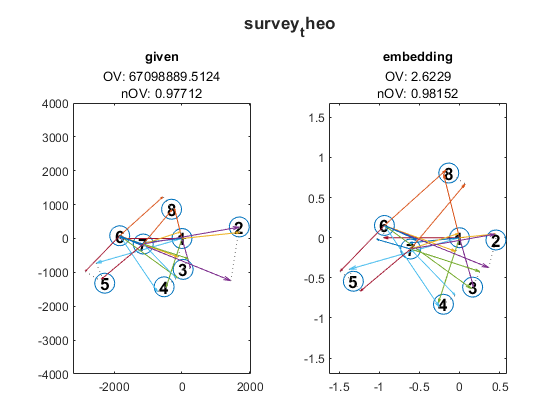

    R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
end


merging...
Elapsed time is 0.004164 seconds.

building M...
Elapsed time is 0.000108 seconds.

building P...
Elapsed time is 0.000062 seconds.


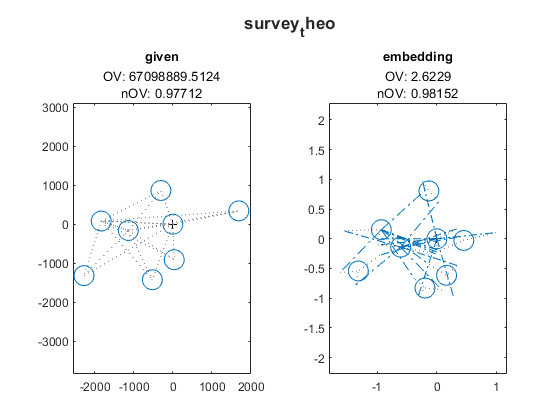

% takes a given file path and forms its content to a distance matrix

function D = readDistanceMatrix(filename)
    f = fopen(filename);
    C = textscan(f, '%f');
    fclose(f); 
    D = squareform(cell2mat(C));
end